# Load Massive Data File

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\');
latestSweep = latestTimeParse(inputPath,'megaSweep');
tic
%Takes about 2 minutes
load(latestSweep)
toc

Elapsed time is 2.672045 seconds.


clear inputPath latestSweep

% tic
% sweepData = reconstruct(Kp,Ki,sinfreqsDecimate,hybridOut,hFit,hGain,hPhase,hError,...
%     smoothOut,sGain,sPhase,sError);
% toc
% clear hybridOut hFit hGain hPhase hError smoothOut sGain sPhase sError

# Plot some stuff

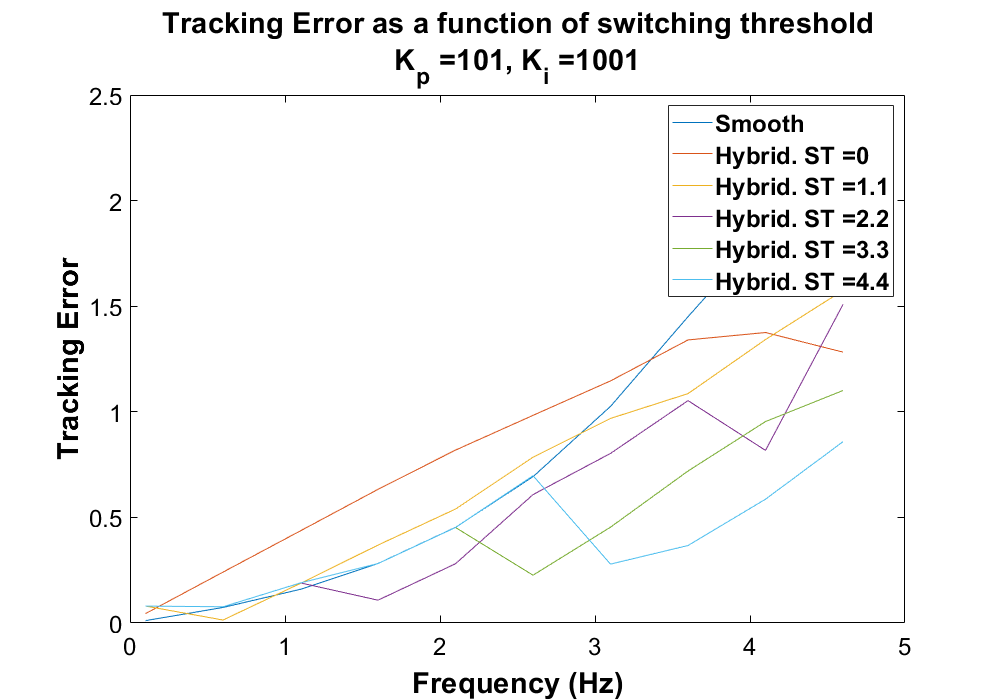

easyPlotter('increasingSwitchThresh','Kp',100,'Ki',1000,sweepData,Kp,Ki,switchThresh,...
    sinfreqsDecimate,pureSinTime,5)

# Plot some other stuff

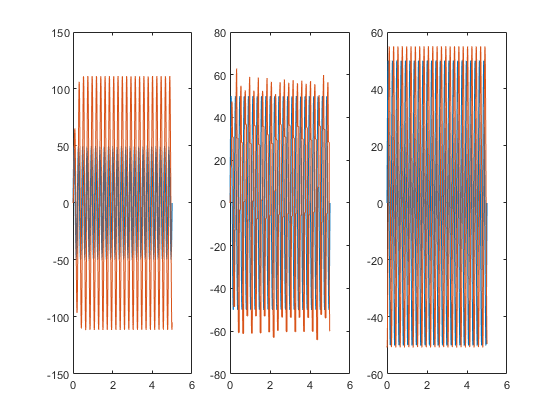

kpIndex = 2

kiIndex = 2

stIndex = 11

fIndex = 10

[kpIndex,kiIndex,stIndex,fIndex] = responsePlot(Kp,Ki,switchThresh,...
    sinfreqsDecimate,150,1000,1,7.1,pureSinTime,sweepData)

sweepData(kpIndex,kiIndex,fIndex)

ans = struct with fields:
            Kp: 101
            Ki: 1001
     inputFreq: 4.6000
     smoothOut: [1001×1 double]
         sGain: 2.1867
        sPhase: -1.2085
        sError: 2.0571
    hybridInfo: [1×51 struct]


sweepData(kpIndex,kiIndex,fIndex).hybridInfo(stIndex)

ans = struct with fields:
    switchThresh: -1
       hybridOut: [1001×1 double]
            hFit: [1001×1 double]
           hGain: 1.0584
          hPhase: 4.5377
          hError: 1.5774


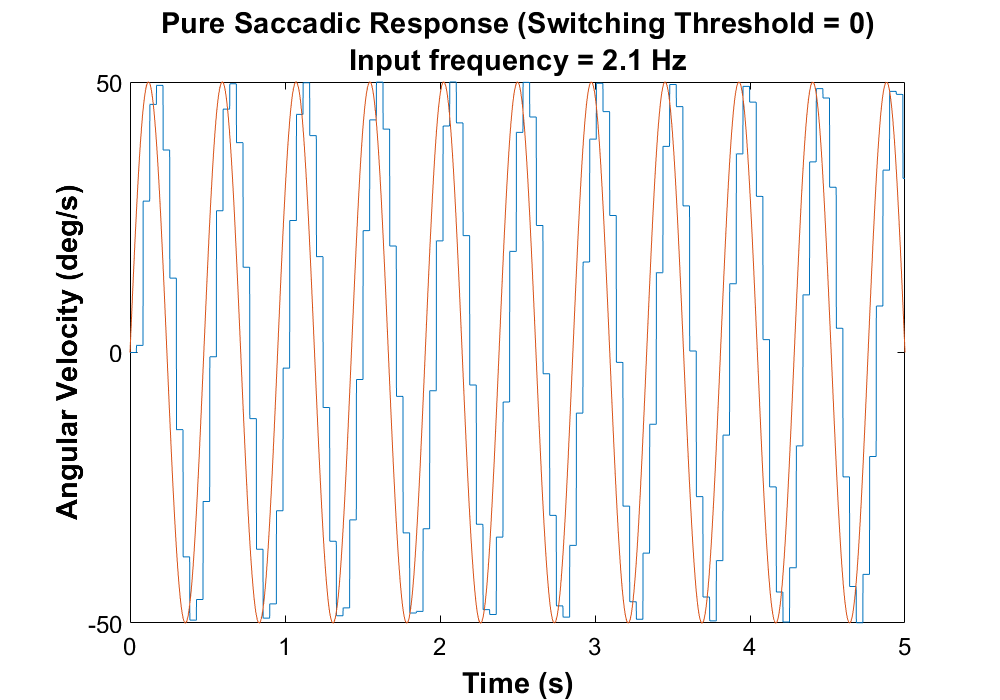

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,1,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Pure Saccadic Response (Switching Threshold = 0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

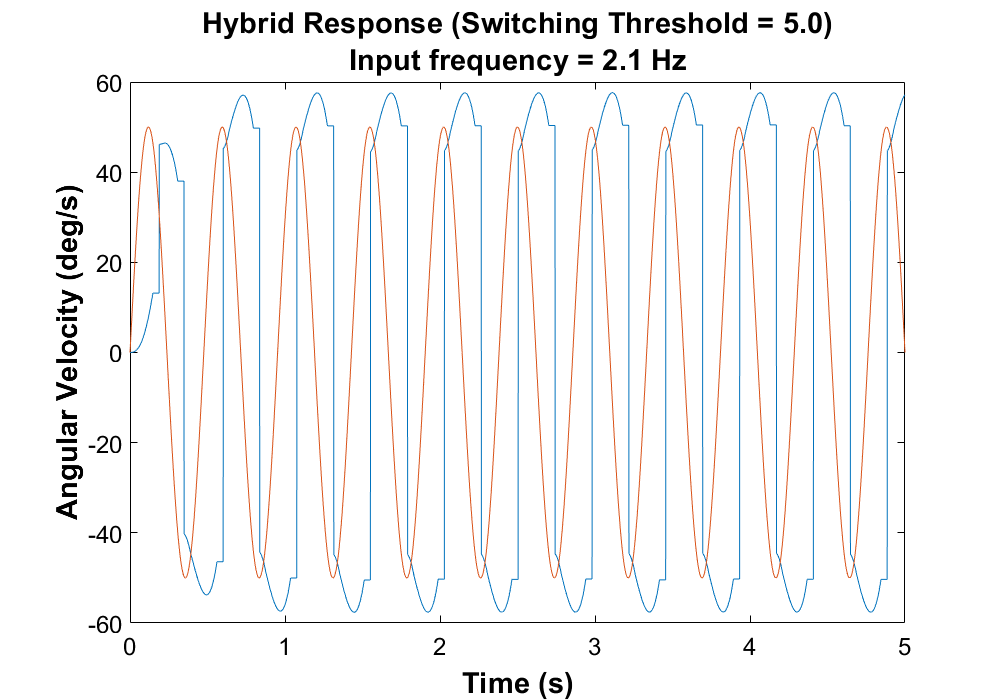


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,11,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response (Switching Threshold = 5.0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

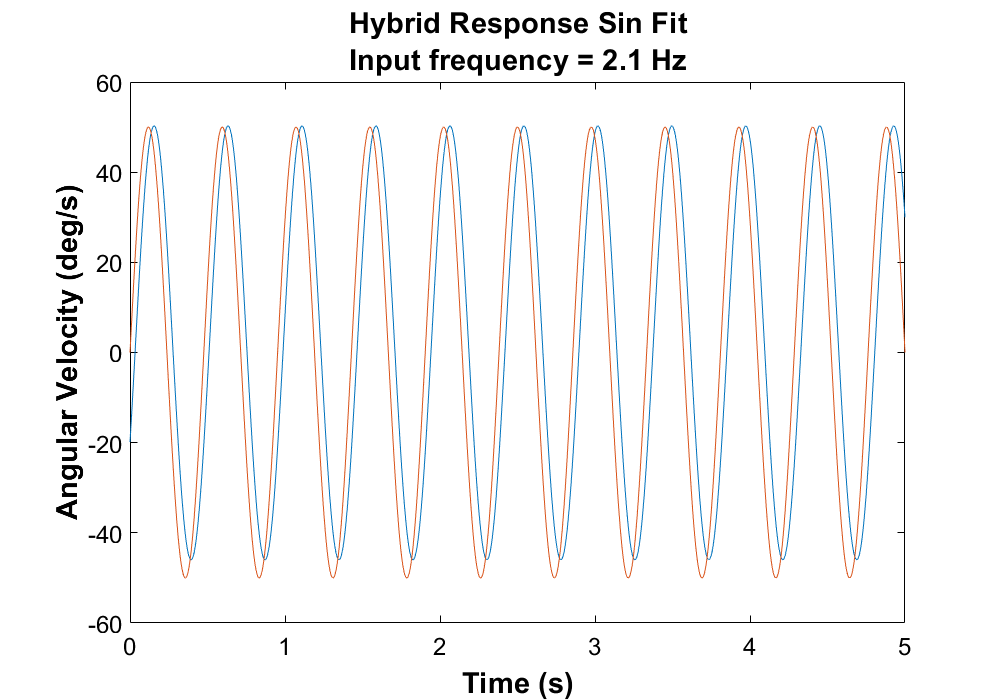


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(5,5,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hFit,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response Sin Fit','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

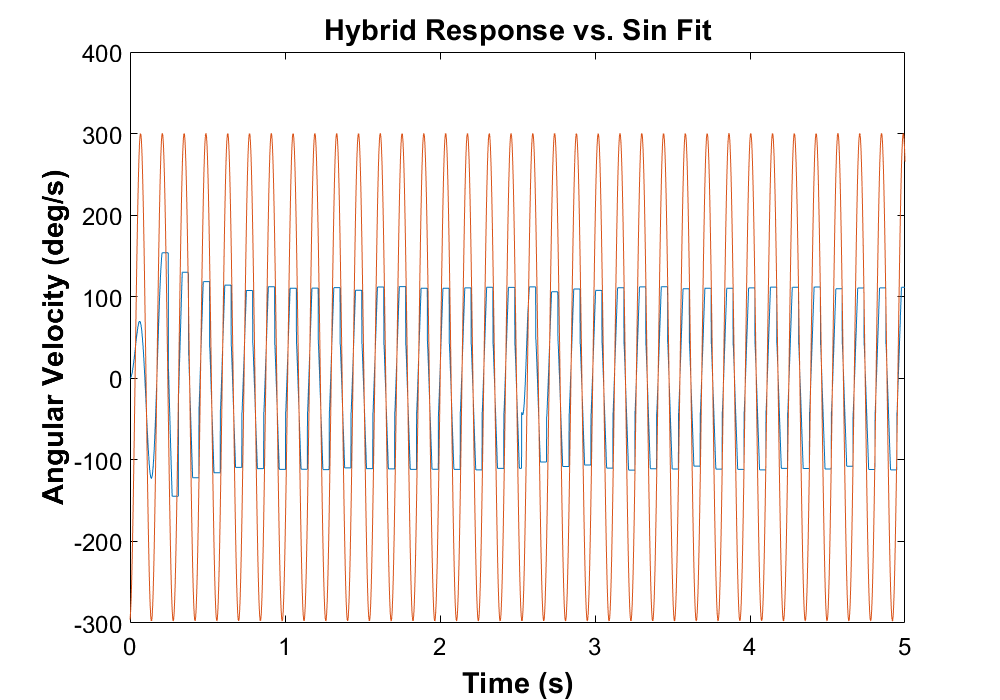


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(9,2,10,15);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,chosenPoint.hFit)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response vs. Sin Fit'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

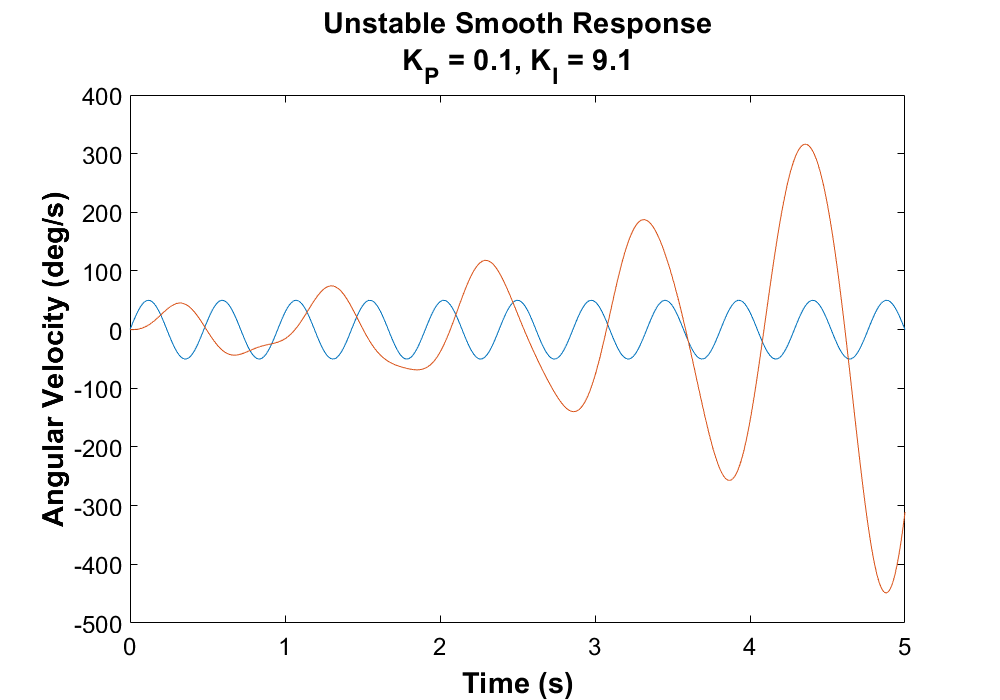



chosenPoint = sweepData(1,10,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
C_tf = tf([0.1 9.1],[1 0]);

%Delay (Pade approximation)
td =.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
den = (1 + num*d_tf);
cl_tf = num/den;

unstable = lsim(cl_tf,sinin,pureSinTime);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(pureSinTime,sinin,pureSinTime,unstable)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Unstable Smooth Response','K_P = 0.1, K_I = 9.1'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')